## **AAE340 HW8 PROBLEM 5    **

close all
clear all
clc

## <5c>

% Defining constants
m = 1.987*10^30;  % Solar mass [kg]
G = 6.673*10^(-11);  % Gravitational constant [m^3/kg^2]

% Solving the differential equation 
tspan = 0:1000:1.000*10^9;  % Time interval [s]
ICs = [0, 0, 0, 1.000*10^12, 2000.0, 0, 12000.0, 4000.0];  % [m] and [m/s]
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % Ode options
[t, z] = ode45(@(t,z) dfcn(t,z), tspan, ICs, options);  % Ode45
x1 = z(:,1);  % Assigning the x1 values
y1 = z(:,2);  % Assigning the y1 values 
x2 = z(:,3);  % Assigning the x2 values
y2 = z(:,4);  % Assigning the y2 values
x1_dot = z(:,5);  % Assigning the x1 dot values
y1_dot = z(:,6);  % Assigning the y1 dot values 
x2_dot = z(:,7);  % Assigning the x2 dot values
y2_dot = z(:,8);  % Assigning the y2 dot values

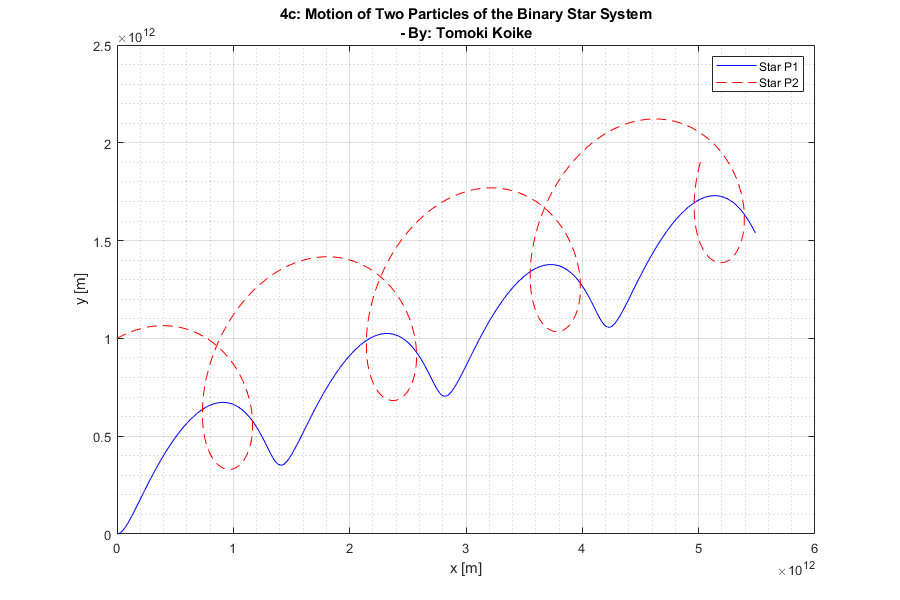

% Plotting
figure('Renderer','painters','Position',[20 20 900 600])
plot(x1, y1, '-b')
xlabel('x [m]')
ylabel('y [m]')
title({'4c: Motion of Two Particles of the Binary Star System',['- By: ' ...
    'Tomoki Koike']})
hold on
plot(x2, y2, '--r')
hold off
grid on
grid minor
box on
legend('Star P1', 'Star P2')

## <4d>

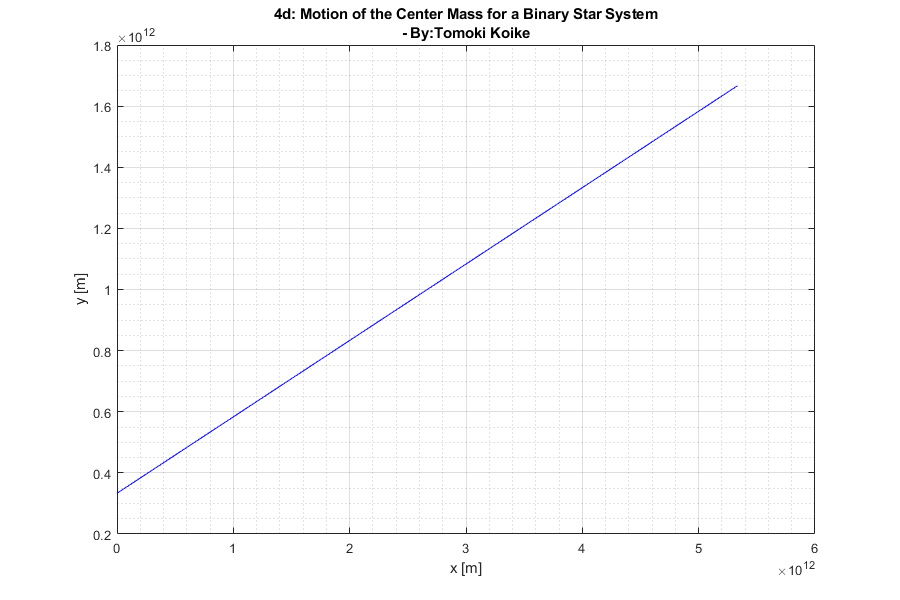

% Defining the position of the center of mass
x_c = (2*x1 + x2)/3;  % x-positions
y_c = (2*y1 + y2)/3;  % y-positions

% Plotting
figure('Renderer','painters',"Position",[20 20 900 600])
plot(x_c, y_c, '-b')
xlabel('x [m]')
ylabel('y [m]')
title({'4d: Motion of the Center Mass for a Binary Star System', ['- By:' ...
    'Tomoki Koike']})
grid on
grid minor
box on

## <4e>

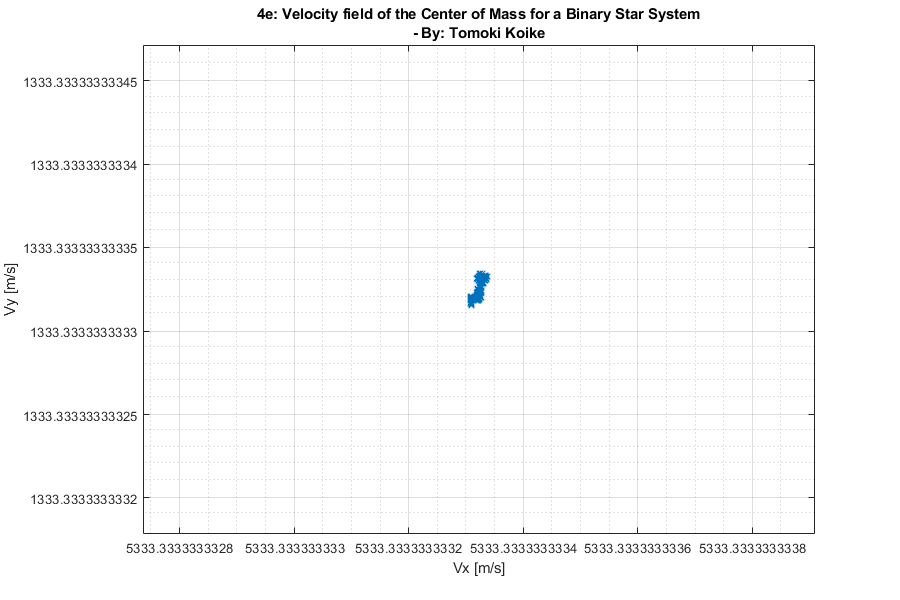

% Defining the velocity vector of the center of mass
x_c_dot = (2*x1_dot + x2_dot)/3;  % e1 direction
y_c_dot = (2*y1_dot + y2_dot)/3;  % e2 direction

% Plotting
figure('Renderer','painters','Position',[20 20 900 600])
plot(x_c_dot, y_c_dot, 'x')
xlabel('Vx [m/s]')
ylabel('Vy [m/s]')
title({'4e: Velocity field of the Center of Mass for a Binary Star System', ['- ' ...
    'By: Tomoki Koike']})
grid on
grid minor
box on

## <4f>

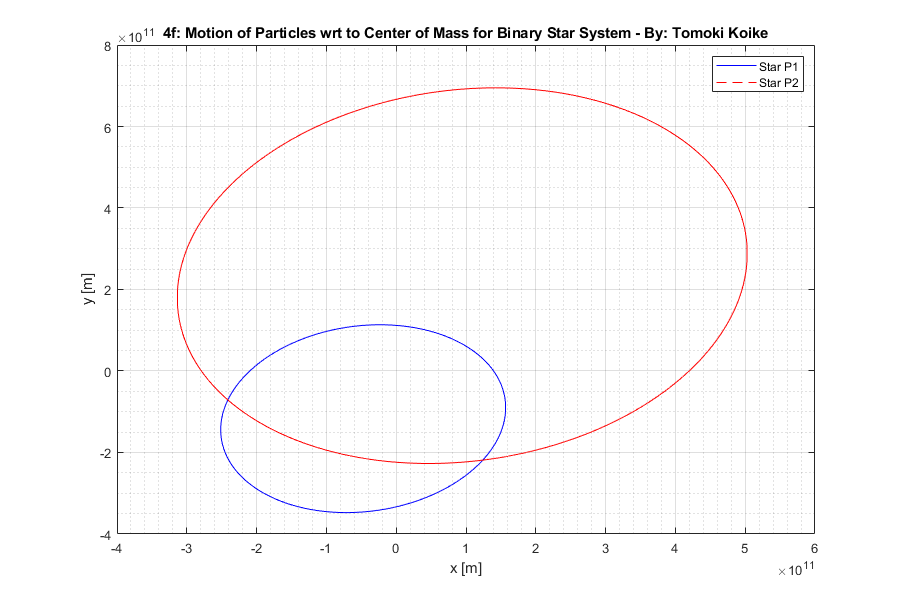

% Defining the position of particles with respect to the center of mass
p1_x = x1 - x_c;  % Particle 1 x position wrt to center of mass
p1_y = y1 - y_c;  % Particle 1 y position wrt to center of mass
p2_x = x2 - x_c;  % Particle 2 x position wrt to center of mass
p2_y = y2 - y_c;  % Particle 2 y position wrt to center of mass

% Plotting
figure('Renderer','painters','Position',[20 20 900 600])
plot(p1_x, p1_y, '-b')
xlabel('x [m]')
ylabel('y [m]')
title({['4f: Motion of Particles wrt to Center of Mass for Binary Star' ...
    ' System', ' - By: Tomoki Koike']})
hold on
plot(p2_x, p2_y, '--r')
hold off
grid on
grid minor
box on
legend('Star P1', 'Star P2')

## Function

function dzdt = dfcn(t,z)
    % Defining constants
    m = 1.987*10^30;  % Solar mass [kg]
    G = 6.673*10^(-11);  % Gravitational constant [m^3/kg^2]
    
    dzdt = zeros(8,1);  % Preallocate the derivative term vector
    % State variable forms
    dzdt(1) = z(5);
    dzdt(2) = z(6);
    dzdt(3) = z(7);
    dzdt(4) = z(8);
    dzdt(5) = (G*m*(z(3)-z(1))) / (2*((z(1)-z(3))^2 + (z(2)-z(4))^2)^(1.5));
    dzdt(6) = (G*m*(z(4)-z(2))) / (2*((z(1)-z(3))^2 + (z(2)-z(4))^2)^(1.5));
    dzdt(7) = (G*m*(z(1)-z(3))) / (((z(1)-z(3))^2 + (z(2)-z(4))^2)^(1.5));
    dzdt(8) = (G*m*(z(2)-z(4))) / (((z(1)-z(3))^2 + (z(2)-z(4))^2)^(1.5));    
end